%close all; clc; clear;
% 초기 위치 및 목표 위치 설정
initial_positions = [0, 0, 0; 20, 10, pi; 20, 0, pi; 0, 10, 0];
goal_positions = [20, 10, 0; 0, 0, pi; 0, 10, pi; 20, 0, 0];
target_vector=initial_positions(:,1:2)-goal_positions(:,1:2);
num_agents = size(initial_positions, 1);
% 시뮬레이션 파라미터 설정
dt = 0.1; % 시간 간격
max_iters = 10000; % 최대 반복 횟수
min_distance = 2; % 최소 거리
repulsion_distance = 3; % 충돌 방지 거리
attraction_gain = 1.0; % 목표 지점으로의 끌림 강도
repulsion_gain = 1000.0; % 반발 강도
max_speed = 1.0; % 최대 속도
max_turn_rate = pi/4; % 최대 회전율
randomness = 0.1; % 랜덤성 강도 

% Dubins 경로 객체 설정
dubConnObj = dubinsConnection;
%dubConnObj.MinTurningRadius = 0.5;

% 에이전트 위치 초기화
positions = initial_positions;
velocities = zeros(num_agents, 2); % [v, omega]
stopped_agents = false(num_agents, 1); % 멈춘 에이전트를 추적
pathPoints = cell(num_agents, 1); % 각 에이전트의 경로 점 저장
use_dubins = true(num_agents, 1); % Dubins 경로 사용 여부
arrived = false(num_agents, 1); % Dubins 경로 사용 여부
%front_back=false(num_agents, 1);

paths = cell(num_agents, 1)% trajectories

paths = 4×1 cell 배열
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


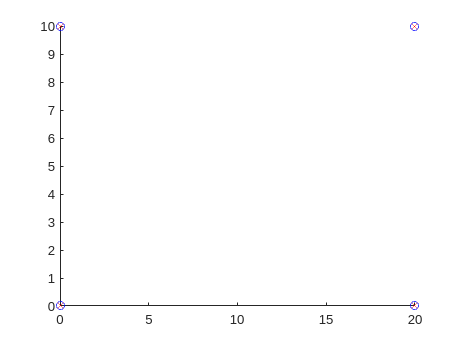

All agents have reached their goals.




% 우선순위 설정 (에이전트 1이 가장 높은 우선순위)
priorities = 1:num_agents;

% 시뮬레이션 시작
for iter = 1:max_iters
    clf;
    hold on;
    % 우선순위에 따라 에이전트 이동
    for p = 1:num_agents
        i = priorities(p);
        goal_vector = goal_positions(i, 1:2) - positions(i, 1:2);
        goal_distance = norm(goal_vector);
        
        % 목표 지점으로의 끌림 강도 계산
        if goal_distance > 0.1
            attraction_force = attraction_gain * goal_vector / goal_distance;
        else
            attraction_force = [0, 0];
        end
        
        % 목표 지점 근처에서 속도 감소
        % if goal_distance < slow_distance
        %     attraction_force = attraction_force * goal_distance / slow_distance;
        % end
        
        repulsion_force = [0, 0];
        use_potential_field = false;
        
        % 다른 에이전트와의 거리 유지
        for j = 1:num_agents
            if i ~= j
                distance_vector = positions(i, 1:2) - positions(j, 1:2);
                distance = norm(distance_vector);
                %dot(distance_vector,target_vector(i,:))

                if distance < min_distance 
                    stopped_agents(i)=true;
                    %fprintf("stopped agent %f\n",i);
                end
                 
                if distance < repulsion_distance 
                    repulsion_force = repulsion_force + repulsion_gain * (1/distance - 1/repulsion_distance) * (distance_vector / distance^2);
                    use_potential_field = true;
                end
            end
        end

        
        % 힘 벡터를 기반으로 이동 결정
        if use_potential_field
            % Potential field를 사용하는 경우
            total_force = attraction_force + repulsion_force;
            total_force = total_force + randomness * (rand(1, 2) - 0.5);
            v = 1;%min(max_speed, norm(total_force));
            if v > 0
                desired_angle = atan2(total_force(2), total_force(1));
                angle_diff = wrapToPi(desired_angle - positions(i, 3));
                omega = max(-max_turn_rate, min(max_turn_rate, angle_diff / dt));
            else
                omega = 0;
            end     

            if stopped_agents(i) && dot(distance_vector,target_vector(i,:)) > 0 %상대차량이 내뒤에있는지 확인
                %fprintf("force zero");
                v=0;
            end
            
            velocities(i, :) = [v, omega];
            positions(i, 1) = positions(i, 1) + velocities(i, 1) * cos(positions(i, 3)) * dt;
            positions(i, 2) = positions(i, 2) + velocities(i, 1) * sin(positions(i, 3)) * dt;
            positions(i, 3) = positions(i, 3) + velocities(i, 2) * dt;
            use_dubins(i) = true; % Potential field 사용 후에는 다시 Dubins 경로를 사용하도록 설정
        elseif not(arrived(i))
            % Dubins 경로를 따름
            if use_dubins(i)
                [pathSegObj, ~] = connect(dubConnObj, positions(i,:), goal_positions(i,:));
                path_length = pathSegObj{1}.Length;
                num_points = max(10, round(path_length * 100)); % 경로 길이에 따라 점의 개수 조정
                pathPoints{i} = interpolate(pathSegObj{1}, linspace(0, path_length, num_points));
                use_dubins(i) = false;
            end
            % 저장된 Dubins 경로의 10번째 이후 위치로 이동
            currentIndex = find(all(abs(pathPoints{i}(:, 1:2) - positions(i, 1:2)) < 1e-2, 2), 1);
            if isempty(currentIndex)
                currentIndex = 1;
            end
            nextIndex = min(currentIndex + 10, size(pathPoints{i}, 1));
            positions(i,:) = pathPoints{i}(nextIndex, :);
            if positions(vecnorm(positions(i,:) - goal_positions(i,:), 2, 2) < 0.1)
                arrived(i)=true;
            end
        end    

        if isempty(paths{i})
            paths{i} = positions(i, 1:2);
        else
            paths{i} = [paths{i}; positions(i, 1:2)];
        end
    end

    if any(stopped_agents) && use_potential_field
        moving_agent = find(stopped_agents, 1);
        if ~isempty(moving_agent)
            goal_vector = goal_positions(moving_agent, 1:2) - positions(moving_agent, 1:2);
            goal_distance = norm(goal_vector);
            attraction_force = attraction_gain * goal_vector / goal_distance;
            repulsion_force = [0, 0];
            
            for j = 1:num_agents
                if moving_agent ~= j
                    distance_vector = positions(moving_agent, 1:2) - positions(j, 1:2);
                    distance = norm(distance_vector);
                    
                    if distance < repulsion_distance
                        repulsion_force = repulsion_force + repulsion_gain * (1/distance - 1/repulsion_distance) * (distance_vector / distance^2);
                    end
                end
            end
            
            total_force = attraction_force + repulsion_force + randomness * (rand(1, 2) - 0.5);
            v = 1;%min(max_speed, norm(total_force));
            if v > 0
                desired_angle = atan2(total_force(2), total_force(1));
                angle_diff = wrapToPi(desired_angle - positions(moving_agent, 3));
                omega = max(-max_turn_rate, min(max_turn_rate, angle_diff / dt));
            else
                omega = 0;
            end
            
            velocities(moving_agent, :) = [v, omega];
            stopped_agents(moving_agent) = false;
        end
        % 위치 업데이트 (Dubins car 모델 사용)
        positions(moving_agent, 1) = positions(moving_agent, 1) + velocities(moving_agent, 1) * cos(positions(moving_agent, 3)) * dt;
        positions(moving_agent, 2) = positions(moving_agent, 2) + velocities(moving_agent, 1) * sin(positions(moving_agent, 3)) * dt;
        positions(moving_agent, 3) = positions(moving_agent, 3) + velocities(moving_agent, 2) * dt;

        paths{moving_agent} = [paths{moving_agent}; positions(moving_agent, 1:2)];
    
    
    end
    

    %arrived

    % % 현재 위치 시각화
    plot(positions(:,1), positions(:,2), 'bo');
    plot(goal_positions(:,1), goal_positions(:,2), 'rx');
    quiver(positions(:,1), positions(:,2), cos(positions(:,3)), sin(positions(:,3)), 0.5, 'r');
    xlim([0, 20]);
    ylim([0, 10]);
    drawnow;
    
    % 목표 지점 도달 확인
    if all(arrived)
        disp('All agents have reached their goals.');
        break;
    end
    
    % 우선순위 랜덤 셔플
    priorities = priorities(randperm(num_agents));
end

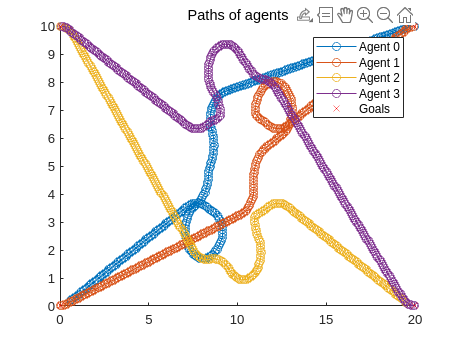


if iter == max_iters
    disp('Max iterations reached.');
end


% 각 에이전트의 경로 시각화
figure;
hold on;
for i = 1:num_agents
    plot(paths{i}(:,1), paths{i}(:,2), '-o');
end
plot(goal_positions(:,1), goal_positions(:,2), 'rx');
xlim([0, 20]);
ylim([0, 10]);
title('Paths of agents');
legend('Agent 0', 'Agent 1', 'Agent 2', 'Agent 3', 'Goals');
hold off;